# 清空数据

clc 
clear

## 初始化网格

global Nx Ny; %#ok<GVMIS>
Nx = 60; Ny = 60;
mesh = ConstuctMesh([Nx,Ny],[1,1]);

## 初始化松弛因子

%矩阵松弛
MAlpha_U = 0.7;
MAlpha_P = 0.3;
%物理场松弛
FAlpha_U = 0.7;
FAlpha_P = 0.3;

## 初始化PISO算法控制

%% 初始化PISO算法控制
dt = 0.01;
ntimeStep = 451;
nPCorrects = 2;
piso = piso(dt,ntimeStep,nPCorrects);

## 初始化物理参数

nu = 0.01;%流体粘度

## 初始化物理场

U = generatefield(mesh,fieldDimension.vol,fieldType.vector);%流体速度场
P = generatefield(mesh,fieldDimension.vol,fieldType.scalar);%流体压力场

## 初始化边界条件

U = setBoundaryCondition(U,[0,0,0],BCType.Dirichlet,BCSelect.w);
U = setBoundaryCondition(U,[0,0,0],BCType.Dirichlet,BCSelect.e);
U = setBoundaryCondition(U,[0,0,0],BCType.Dirichlet,BCSelect.s);
U = setBoundaryCondition(U,[1,0,0],BCType.Dirichlet,BCSelect.n);

P = setBoundaryCondition(P,0,BCType.Neumann,BCSelect.w);
P = setBoundaryCondition(P,0,BCType.Neumann,BCSelect.e);
P = setBoundaryCondition(P,0,BCType.Neumann,BCSelect.s);
P = setBoundaryCondition(P,0,BCType.Neumann,BCSelect.n);

## 初始化中间变量场

phi = generatefield(mesh,fieldDimension.face,fieldType.scalar);
phi = calculatePhi(mesh,phi,U);

## 初始化残差统计

RES = initialRes(1e4,'mass','momentum','P');

## 矩阵组装和求解

%% 矩阵组装和求解
tic
while piso.loop(piso)
    %计算中间变量场
    Pgrad_F = grad_fvc(mesh,P,gradScheme.Gauss,gradType.field);
    Pgrad_Su = grad_fvc(mesh,P,gradScheme.Gauss,gradType.Su);
    %计算速度场算子
    ddt_U = ddt_fvm(mesh,piso,ddtScheme.Euler,U);
    div_U = div_fvm(mesh,phi,divScheme.upwind,U);
    lap_U = laplace_fvm(mesh,nu,laplaceScheme.Gauss,U);
    %速度场矩阵松弛求解
    [UEqn,U] = matrixSystem(U,[div_U,lap_U,Pgrad_Su],['+','-','-'],IS.solve,MAlpha_U);
    %记录压力修正前的初始压力场值
    Pold = copyField(mesh,P);
    %内循环第一次压力迭代修正(默认最少修正1次)
    %计算质量源项(mass)和修正压力场(P')的离散矩阵系数(DApf)
    [mass,DAp,DApf,Uf] = PWIM(mesh,UEqn,U,P,RCType.ur);
    %构建修正压力(P')方程
    PEqn = laplace_fvm(mesh,DApf,laplaceScheme.Gauss,P);
    %设置参考压力
    PEqn = setPref(PEqn,3,0);
    %计算修正压力(P')
    [PEqn,P] = matrixSystem(P,[PEqn,mass],['-','-'],IS.solve);
    %RESULT2 = outputField(mesh,outputSelect.smooth,color.RdBu11,P);
    %内循环压力迭代修正
    while piso.pCorrect(piso)
        %内循环多次修正压力源项组装
        %计算质量修正值
        [massPrime,PEqn] = PRIME(mesh,DAp,UEqn,P,PEqn,Pgrad_Su);
        %合并质量场
        allMass = addField(mass,massPrime);
        %构建两次修正压力方程总和的压力矩阵
        PEqn2 = laplace_fvm(mesh,DApf,laplaceScheme.Gauss,P);
        %设置参考压力
        PEqn2 = setPref(PEqn2,3,0);
        [PEqn2,P] = matrixSystem(P,[PEqn2,allMass],['-','-'],IS.solve);
        % RESULT2 = outputField(mesh,outputSelect.smooth,color.RdBu11,P);
        PEqn2.oldFields = Pold.fields.x;
        %压力修正方程不变，仅质量修正多次累加
    end
    %修正质量通量场
    phi = correctMf(mesh,phi,Uf,P,DApf);
    %修正速度(U)和压力场(P)
    [U,P] = correctUP(mesh,U,DAp,P,PEqn,PEqnType.cp); 
    %计算残差
    % RES = piso.iteraRes(piso,RES,U,UEqn,'momentum');
    % RES = piso.iteraRes(piso,RES,P,PEqn,'P'); 
    % RES = piso.massRes(piso,RES,mass); 
    %绘制残差
    % piso.plotRES(piso,RES); 
    % RESULT1 = outputField(mesh,outputSelect.smooth,color.RdBu11,U);
    % RESULT2 = outputField(mesh,outputSelect.smooth,color.RdBu11,P);
end

PISO算法迭代开始：
PISO:当前迭代步为0,

bicgstab 在解的 迭代 9 处收敛，并且相对残差为 8.6e-07。
右侧向量均为零，因此 bicgstab
返回全部为零的解，而不会进行迭代。


PISO：当前时间步为1.000000e-02：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.000000e-02,

bicgstab 在解的 迭代 10 处收敛，并且相对残差为 5.7e-07。
bicgstab 在解的 迭代 10.5 处收敛，并且相对残差为 5.2e-07。


PISO：当前时间步为2.000000e-02：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.000000e-02,

bicgstab 在解的 迭代 10.5 处收敛，并且相对残差为 6.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


PISO：当前时间步为3.000000e-02：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.000000e-02,

bicgstab 在解的 迭代 10 处收敛，并且相对残差为 6.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 5.7e-07。


PISO：当前时间步为4.000000e-02：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.000000e-02,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 4.4e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为5.000000e-02：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为5.000000e-02,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为6.000000e-02：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为6.000000e-02,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 4.9e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.4e-07。


PISO：当前时间步为7.000000e-02：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为7.000000e-02,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为8.000000e-02：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为8.000000e-02,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 5.4e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 4.8e-07。


PISO：当前时间步为9.000000e-02：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为9.000000e-02,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 6.1e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.4e-07。


PISO：当前时间步为1.000000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.000000e-01,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 5.3e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.2e-07。


PISO：当前时间步为1.100000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.100000e-01,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 4.6e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.5e-07。


PISO：当前时间步为1.200000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.200000e-01,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 4.6e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.4e-07。


PISO：当前时间步为1.300000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.300000e-01,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 4.6e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.2e-07。


PISO：当前时间步为1.400000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.400000e-01,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 4.5e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.1e-07。


PISO：当前时间步为1.500000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.500000e-01,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 4.4e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.2e-07。


PISO：当前时间步为1.600000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.600000e-01,

bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 4.4e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.2e-07。


PISO：当前时间步为1.700000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.700000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 9.6e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.2e-07。


PISO：当前时间步为1.800000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.800000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 9.3e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5.1e-07。


PISO：当前时间步为1.900000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.900000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 9.2e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5e-07。


PISO：当前时间步为2.000000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.000000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 9.2e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5e-07。


PISO：当前时间步为2.100000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.100000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 9.1e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 5e-07。


PISO：当前时间步为2.200000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.200000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 9e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 4.9e-07。


PISO：当前时间步为2.300000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.300000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.8e-07。
bicgstab 在解的 迭代 12.5 处收敛，并且相对残差为 4.9e-07。


PISO：当前时间步为2.400000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.400000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 1e-06。


PISO：当前时间步为2.500000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.500000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.9e-07。


PISO：当前时间步为2.600000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.600000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.8e-07。


PISO：当前时间步为2.700000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.700000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.8e-07。


PISO：当前时间步为2.800000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.800000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.5e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.7e-07。


PISO：当前时间步为2.900000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.900000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.5e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.6e-07。


PISO：当前时间步为3.000000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.000000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.4e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.6e-07。


PISO：当前时间步为3.100000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.100000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.4e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.5e-07。


PISO：当前时间步为3.200000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.200000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.4e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.4e-07。


PISO：当前时间步为3.300000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.300000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.3e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.4e-07。


PISO：当前时间步为3.400000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.400000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.3e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.3e-07。


PISO：当前时间步为3.500000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.500000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.3e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.3e-07。


PISO：当前时间步为3.600000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.600000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.2e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.2e-07。


PISO：当前时间步为3.700000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.700000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.2e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.2e-07。


PISO：当前时间步为3.800000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.800000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.2e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.1e-07。


PISO：当前时间步为3.900000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.900000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.2e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9.1e-07。


PISO：当前时间步为4.000000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.000000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.1e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 9e-07。


PISO：当前时间步为4.100000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.100000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.1e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为4.200000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.200000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.1e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为4.300000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.300000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.1e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为4.400000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.400000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8.1e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为4.500000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.500000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为4.600000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.600000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为4.700000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.700000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为4.800000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.800000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为4.900000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.900000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为5.000000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为5.000000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为5.100000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为5.100000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为5.200000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为5.200000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为5.300000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为5.300000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为5.400000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为5.400000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为5.500000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为5.500000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为5.600000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为5.600000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为5.700000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为5.700000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为5.800000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为5.800000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.9e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为5.900000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为5.900000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为6.000000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为6.000000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为6.100000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为6.100000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为6.200000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为6.200000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为6.300000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为6.300000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为6.400000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为6.400000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为6.500000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为6.500000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为6.600000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为6.600000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为6.700000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为6.700000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为6.800000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为6.800000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.8e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为6.900000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为6.900000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.9e-07。


PISO：当前时间步为7.000000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为7.000000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.9e-07。


PISO：当前时间步为7.100000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为7.100000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.9e-07。


PISO：当前时间步为7.200000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为7.200000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.9e-07。


PISO：当前时间步为7.300000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为7.300000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.8e-07。


PISO：当前时间步为7.400000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为7.400000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.8e-07。


PISO：当前时间步为7.500000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为7.500000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.8e-07。


PISO：当前时间步为7.600000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为7.600000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.8e-07。


PISO：当前时间步为7.700000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为7.700000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.7e-07。


PISO：当前时间步为7.800000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为7.800000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.7e-07。


PISO：当前时间步为7.900000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为7.900000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.7e-07。


PISO：当前时间步为8.000000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为8.000000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.7e-07。


PISO：当前时间步为8.100000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为8.100000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.6e-07。


PISO：当前时间步为8.200000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为8.200000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.7e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.6e-07。


PISO：当前时间步为8.300000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为8.300000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.6e-07。


PISO：当前时间步为8.400000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为8.400000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.6e-07。


PISO：当前时间步为8.500000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为8.500000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.6e-07。


PISO：当前时间步为8.600000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为8.600000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.5e-07。


PISO：当前时间步为8.700000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为8.700000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.5e-07。


PISO：当前时间步为8.800000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为8.800000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.5e-07。


PISO：当前时间步为8.900000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为8.900000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.5e-07。


PISO：当前时间步为9.000000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为9.000000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.5e-07。


PISO：当前时间步为9.100000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为9.100000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.4e-07。


PISO：当前时间步为9.200000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为9.200000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.4e-07。


PISO：当前时间步为9.300000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为9.300000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.4e-07。


PISO：当前时间步为9.400000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为9.400000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.4e-07。


PISO：当前时间步为9.500000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为9.500000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.4e-07。


PISO：当前时间步为9.600000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为9.600000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.4e-07。


PISO：当前时间步为9.700000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为9.700000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.3e-07。


PISO：当前时间步为9.800000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为9.800000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.6e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.3e-07。


PISO：当前时间步为9.900000e-01：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为9.900000e-01,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.3e-07。


PISO：当前时间步为1.000000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.000000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 12 处收敛，并且相对残差为 7.3e-07。


PISO：当前时间步为1.010000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.010000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 1e-06。


PISO：当前时间步为1.020000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.020000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 1e-06。


PISO：当前时间步为1.030000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.030000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.9e-07。


PISO：当前时间步为1.040000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.040000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.9e-07。


PISO：当前时间步为1.050000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.050000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.9e-07。


PISO：当前时间步为1.060000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.060000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.9e-07。


PISO：当前时间步为1.070000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.070000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.9e-07。


PISO：当前时间步为1.080000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.080000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.8e-07。


PISO：当前时间步为1.090000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.090000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.8e-07。


PISO：当前时间步为1.100000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.100000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.8e-07。


PISO：当前时间步为1.110000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.110000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.8e-07。


PISO：当前时间步为1.120000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.120000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.8e-07。


PISO：当前时间步为1.130000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.130000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.7e-07。


PISO：当前时间步为1.140000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.140000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.7e-07。


PISO：当前时间步为1.150000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.150000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.7e-07。


PISO：当前时间步为1.160000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.160000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.7e-07。


PISO：当前时间步为1.170000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.170000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.7e-07。


PISO：当前时间步为1.180000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.180000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.6e-07。


PISO：当前时间步为1.190000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.190000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.5e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.6e-07。


PISO：当前时间步为1.200000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.200000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.6e-07。


PISO：当前时间步为1.210000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.210000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.6e-07。


PISO：当前时间步为1.220000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.220000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.6e-07。


PISO：当前时间步为1.230000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.230000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.6e-07。


PISO：当前时间步为1.240000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.240000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.5e-07。


PISO：当前时间步为1.250000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.250000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.5e-07。


PISO：当前时间步为1.260000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.260000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.5e-07。


PISO：当前时间步为1.270000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.270000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.5e-07。


PISO：当前时间步为1.280000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.280000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.5e-07。


PISO：当前时间步为1.290000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.290000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.5e-07。


PISO：当前时间步为1.300000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.300000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.4e-07。


PISO：当前时间步为1.310000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.310000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.4e-07。


PISO：当前时间步为1.320000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.320000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.4e-07。


PISO：当前时间步为1.330000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.330000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.4e-07。


PISO：当前时间步为1.340000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.340000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.4e-07。


PISO：当前时间步为1.350000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.350000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.4e-07。


PISO：当前时间步为1.360000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.360000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


PISO：当前时间步为1.370000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.370000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


PISO：当前时间步为1.380000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.380000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


PISO：当前时间步为1.390000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.390000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


PISO：当前时间步为1.400000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.400000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


PISO：当前时间步为1.410000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.410000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


PISO：当前时间步为1.420000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.420000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.3e-07。


PISO：当前时间步为1.430000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.430000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.4e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


PISO：当前时间步为1.440000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.440000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


PISO：当前时间步为1.450000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.450000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


PISO：当前时间步为1.460000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.460000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


PISO：当前时间步为1.470000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.470000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


PISO：当前时间步为1.480000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.480000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


PISO：当前时间步为1.490000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.490000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


PISO：当前时间步为1.500000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.500000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.2e-07。


PISO：当前时间步为1.510000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.510000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


PISO：当前时间步为1.520000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.520000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


PISO：当前时间步为1.530000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.530000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


PISO：当前时间步为1.540000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.540000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


PISO：当前时间步为1.550000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.550000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


PISO：当前时间步为1.560000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.560000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


PISO：当前时间步为1.570000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.570000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


PISO：当前时间步为1.580000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.580000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


PISO：当前时间步为1.590000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.590000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9.1e-07。


PISO：当前时间步为1.600000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.600000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


PISO：当前时间步为1.610000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.610000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


PISO：当前时间步为1.620000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.620000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


PISO：当前时间步为1.630000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.630000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


PISO：当前时间步为1.640000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.640000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


PISO：当前时间步为1.650000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.650000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


PISO：当前时间步为1.660000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.660000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


PISO：当前时间步为1.670000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.670000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


PISO：当前时间步为1.680000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.680000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 9e-07。


PISO：当前时间步为1.690000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.690000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为1.700000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.700000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为1.710000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.710000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为1.720000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.720000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.3e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为1.730000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.730000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为1.740000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.740000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为1.750000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.750000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为1.760000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.760000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为1.770000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.770000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为1.780000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.780000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.9e-07。


PISO：当前时间步为1.790000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.790000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为1.800000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.800000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为1.810000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.810000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为1.820000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.820000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为1.830000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.830000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为1.840000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.840000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为1.850000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.850000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为1.860000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.860000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为1.870000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.870000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为1.880000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.880000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为1.890000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.890000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为1.900000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.900000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.8e-07。


PISO：当前时间步为1.910000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.910000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为1.920000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.920000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为1.930000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.930000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为1.940000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.940000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为1.950000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.950000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为1.960000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.960000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为1.970000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.970000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为1.980000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.980000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为1.990000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为1.990000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为2.000000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.000000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为2.010000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.010000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为2.020000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.020000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为2.030000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.030000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为2.040000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.040000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.7e-07。


PISO：当前时间步为2.050000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.050000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.060000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.060000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.070000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.070000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.2e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.080000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.080000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.090000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.090000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.100000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.100000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.110000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.110000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.120000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.120000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.130000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.130000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.140000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.140000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.150000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.150000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.160000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.160000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.170000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.170000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.180000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.180000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.190000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.190000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.6e-07。


PISO：当前时间步为2.200000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.200000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.210000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.210000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.220000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.220000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.230000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.230000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.240000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.240000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.250000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.250000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.260000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.260000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.270000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.270000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.280000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.280000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.290000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.290000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.300000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.300000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.310000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.310000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.320000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.320000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.330000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.330000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.340000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.340000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.350000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.350000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.360000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.360000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.370000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.370000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.5e-07。


PISO：当前时间步为2.380000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.380000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.390000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.390000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.400000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.400000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.410000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.410000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.420000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.420000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.430000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.430000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.440000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.440000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.450000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.450000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.460000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.460000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.470000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.470000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.480000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.480000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.490000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.490000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.500000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.500000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.510000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.510000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.520000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.520000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7.1e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.530000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.530000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.540000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.540000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.550000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.550000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.560000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.560000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.570000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.570000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.580000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.580000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.590000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.590000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.4e-07。


PISO：当前时间步为2.600000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.600000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.610000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.610000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.620000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.620000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.630000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.630000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.640000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.640000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.650000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.650000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.660000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.660000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.670000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.670000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.680000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.680000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.690000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.690000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.700000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.700000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.710000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.710000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.720000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.720000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.730000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.730000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.740000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.740000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.750000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.750000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.760000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.760000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.770000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.770000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.780000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.780000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.790000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.790000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.800000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.800000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.810000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.810000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.820000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.820000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.830000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.830000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.840000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.840000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.850000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.850000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.860000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.860000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.3e-07。


PISO：当前时间步为2.870000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.870000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为2.880000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.880000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为2.890000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.890000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为2.900000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.900000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为2.910000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.910000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为2.920000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.920000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为2.930000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.930000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为2.940000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.940000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为2.950000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.950000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为2.960000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.960000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为2.970000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.970000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为2.980000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.980000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为2.990000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为2.990000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.000000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.000000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.010000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.010000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.020000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.020000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.030000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.030000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.040000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.040000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.050000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.050000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.060000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.060000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.070000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.070000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.080000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.080000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.090000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.090000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.100000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.100000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.110000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.110000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.120000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.120000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.130000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.130000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.140000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.140000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.150000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.150000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.160000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.160000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.170000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.170000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.180000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.180000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.190000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.190000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 7e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.200000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.200000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.210000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.210000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.220000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.220000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.2e-07。


PISO：当前时间步为3.230000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.230000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.240000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.240000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.250000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.250000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.260000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.260000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.270000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.270000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.280000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.280000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.290000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.290000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.300000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.300000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.310000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.310000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.320000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.320000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.330000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.330000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.340000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.340000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.350000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.350000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.360000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.360000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.370000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.370000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.380000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.380000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.390000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.390000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.400000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.400000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.410000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.410000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.420000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.420000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.430000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.430000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.440000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.440000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.450000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.450000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.460000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.460000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.470000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.470000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.480000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.480000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.490000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.490000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.500000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.500000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.510000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.510000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.520000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.520000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.530000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.530000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.540000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.540000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.550000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.550000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.560000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.560000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.570000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.570000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.580000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.580000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.590000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.590000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.600000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.600000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.610000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.610000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.620000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.620000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.630000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.630000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.640000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.640000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.650000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.650000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.660000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.660000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.670000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.670000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.680000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.680000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.690000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.690000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.700000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.700000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.710000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.710000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.720000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.720000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.730000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.730000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.740000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.740000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.750000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.750000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.760000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.760000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8.1e-07。


PISO：当前时间步为3.770000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.770000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.780000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.780000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.790000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.790000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.800000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.800000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.810000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.810000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.820000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.820000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.830000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.830000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.840000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.840000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.850000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.850000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.860000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.860000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.870000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.870000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.880000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.880000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.890000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.890000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.900000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.900000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.910000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.910000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.920000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.920000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.930000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.930000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.940000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.940000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.950000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.950000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.960000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.960000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.970000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.970000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.980000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.980000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为3.990000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为3.990000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.000000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.000000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.010000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.010000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.020000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.020000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.030000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.030000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.040000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.040000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.050000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.050000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.060000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.060000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.070000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.070000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.080000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.080000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.090000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.090000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.100000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.100000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.110000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.110000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.120000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.120000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.130000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.130000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.140000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.140000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.150000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.150000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.160000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.160000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.170000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.170000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.180000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.180000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.190000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.190000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.200000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.200000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.210000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.210000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.220000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.220000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.230000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.230000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.240000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.240000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.250000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.250000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.260000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.260000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.270000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.270000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.280000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.280000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.290000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.290000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.300000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.300000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.310000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.310000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.320000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.320000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.330000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.330000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.340000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.340000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.350000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.350000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.360000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.360000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.370000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.370000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.380000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.380000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.390000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.390000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.400000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.400000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.410000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.410000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.420000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.420000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.430000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.430000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.440000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.440000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.450000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.450000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.460000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.460000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.470000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.470000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.480000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.480000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.490000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.490000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.500000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO:当前迭代步为4.500000e+00,

bicgstab 在解的 迭代 11 处收敛，并且相对残差为 6.9e-07。
bicgstab 在解的 迭代 11.5 处收敛，并且相对残差为 8e-07。


PISO：当前时间步为4.510000e+00：
PISO：当前压力修正次数为1,
PISO：当前压力修正次数为2,
PISO：压力修正迭代结束。


PISO算法迭代结束。


toc

历时 26.131268 秒。


## 后处理

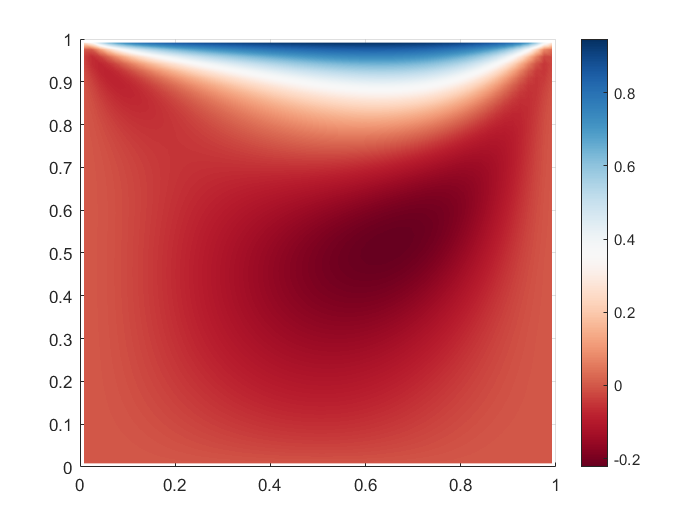

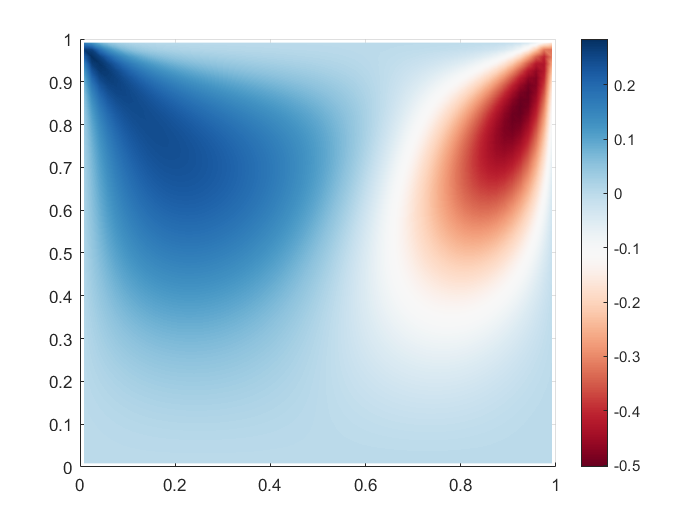

RESULT1 = outputField(mesh,outputSelect.smooth,color.RdBu11,U);

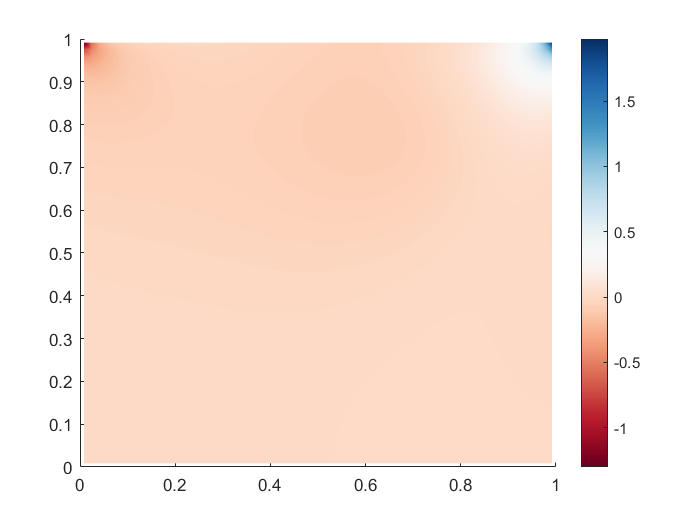

RESULT2 = outputField(mesh,outputSelect.smooth,color.RdBu11,P);

## BenchMark

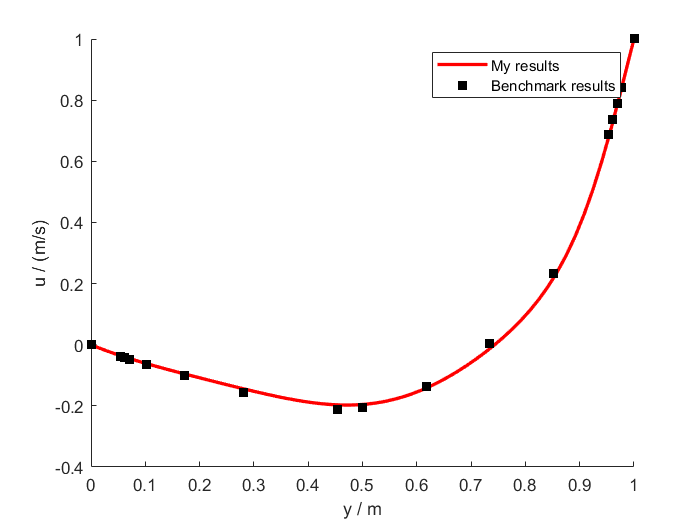

BM_cavity;